Tamás Regan, Henry Tejada Deras        03-31-2025        ENGX2006-01.25SP

# Rubber Band Lab

**ENGX2006-01.25SP**

Our goal in this lab is to find the stiffness and natural length of the 6 rubber bands that will be used in our jungle bridge project. We accomplished this by measuring the length of the rubber bands under different weights, which gave us a series of data points that relates $F\left(\textrm{mass}\;\textrm{of}\;\textrm{the}\;\textrm{weights}*g\right)=m*l+b$ where $l$ is the length of the rubber band while being pulled by the weights. To find the line that best predicts the force applied on the rubber band, you optimize the cost function, 


$$E\left(m,b\right)=\sum_{i=1}^n {\left(m*x_i +b-y_i \right)}^2$$


 (which represents the relationship between length and force) for the smallest difference in your line and the measured force of the data. In this case $x$ is the measured lengths and $y$ is the measured force. The way you optimize the cost function is by taking the derivative of that function and setting it equal to 0, and solving for $m$ and $b$. This will give you the m and b which outputs a line that is as close to every point as possible. The derived formula for this is:

$\left\lbrack \begin{array}{c}
m\\
b
\end{array}\right\rbrack ={\left(A^T A\right)}^{-1} A^T Y$, $Y=\left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
\vdots \\
y_n 
\end{array}\right\rbrack$, and $\left\lbrack \begin{array}{cc}
x_1  & 1\\
x_2  & 1\\
\vdots  & \vdots \\
x_n  & 1
\end{array}\right\rbrack$

Once you have minimized the cost function, you can compare $F=m*l+b$ to $F=k*l+k+l_0$. (The second equation is Hooke’s Law), and because the two equations are of the same form we know this must be true: $k=m$, and $b=-l_0 *k$, so $l_0 =-\frac{b}{k}$. This provides us with the $k$ and $l_0$ values, or stiffness and natural length for any rubber band we have data for.

% Load Data
data = readtable('RubberBandTemplate.xlsx');

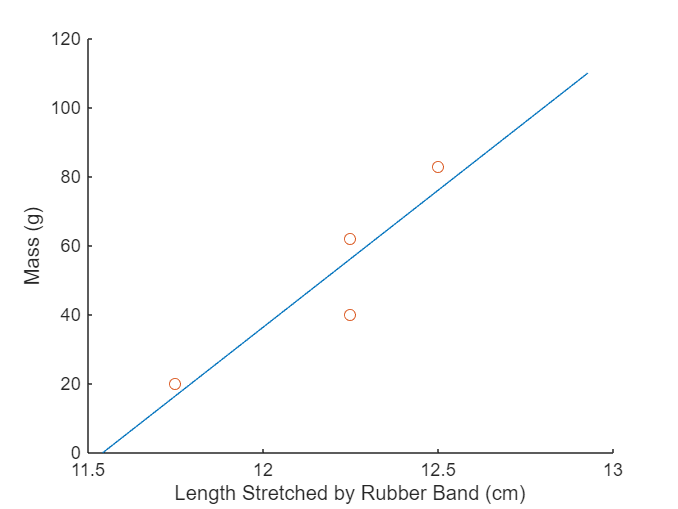


% Get Specified Range of Data
row_range = 1:12;
col_range = 3:6;

% Save data to MATLAB Matrix
data_mat = table2array(data(row_range,col_range));

% Iterate through data of each rubber band (excluding untensed measurement)
for rubber_band = 1:1:(size(data_mat, 1) / 2)
    % Get Mass Hanged from Rubber Band (g)
    mass = data_mat(((rubber_band * 2) - 1), :)';
    % Get Length Rubber Band Stretched (cm)
    length = data_mat((rubber_band * 2), :)';

    % Construct A - [Length Rubber Band Stretched, 1]
    A = [(length ./ 100), ones(size(length, 1), 1)];
    % Construct Y - Force of Weight on Rubber Band (F = ma; a = g = 9.8 m/s^2)
    Y = (mass ./ 1000) .* 9.8;

    % Compute Approximation
    Q = (A' * A) \ (A' * Y);

    % Extract Stiffness (N/m) and Natural Length (m)
    k = Q(1); % Stiffness (N/m)
    l_0 = -1 * Q(2) / Q(1); % Natural Length (m)

    % Store Stiffness (N/m) and Natural Length Values (m)
    stiffness(rubber_band) = k;
    natural_length(rubber_band) = l_0;
end

% Plot Data for Rubber Band #1
rubber_band = 1;
% Get Mass Hanged from Rubber Band (g)
mass = data_mat(((rubber_band * 2) - 1), :)';
% Get Length Rubber Band Stretched (cm)
length = data_mat((rubber_band * 2), :)';

y = linspace(0, 110, 1000); % (g)
x = (((y / 1000) * 9.8 / stiffness(rubber_band)) + natural_length(rubber_band)) * 100; % (cm)

figure
hold on
plot(x, y)
scatter(length, mass)
xlabel('Length Stretched by Rubber Band (cm)')
ylabel('Mass (g)')
hold off


levels = [0:1:1000];

figure
% Define Function
E = @(m, b) (m * (length(1) / 100) + b - (mass(1) / 1000 * 9.8))^2 + (m * (length(2) / 100) + b - (mass(2) / 1000 * 9.8))^2 + (m * (length(3) / 100) + b - (mass(3) / 1000 * 9.8))^2 + (m * (length(4) / 100) + b - (mass(4) / 1000 * 9.8))^2

E = function_handle with value:
    @(m,b)(m*(length(1)/100)+b-(mass(1)/1000*9.8))^2+(m*(length(2)/100)+b-(mass(2)/1000*9.8))^2+(m*(length(3)/100)+b-(mass(3)/1000*9.8))^2+(m*(length(4)/100)+b-(mass(4)/1000*9.8))^2


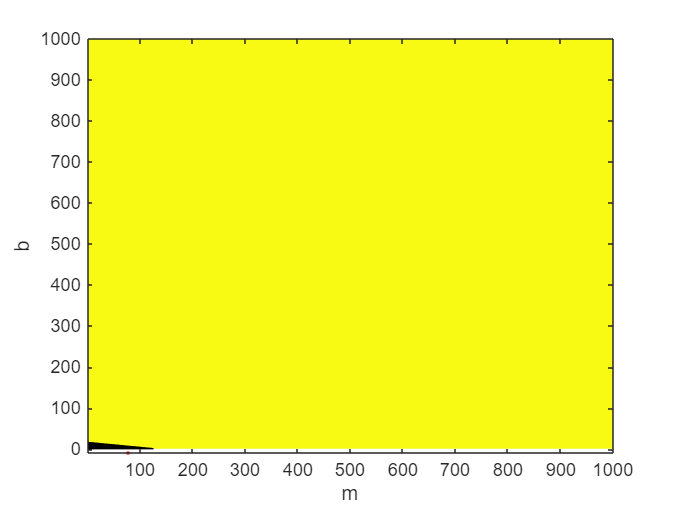

x = 1:1000; y = 1:1000;
[X,Y] = meshgrid(x,y);
E_num = zeros(1000, 1000);
for i = 1:1000
    for j = 1:1000
        E_num(i,j) = E(X(i,j),Y(i,j));
    end
end

contourf(E_num, levels)
% fcontour(E, [-100, 100, -100, 100]);
hold on

xlabel("m")
ylabel("b")
zlabel("E(m, b)")
% colorbar
colormap("parula")

m = 77.7811;
b = -8.9773;
plot3(m, b, E(m, b), 'r.', MarkerSize=5)